% Clear
clear all
close all 
clc

% Defining all constants.
block_len = 64;
prefix_len = 16;
block_channel = 16;
block_signal = 84;
block_num = block_signal + block_channel;
data_len = 48;
no_guards_len = 52;

%% Generating data to send.
%{
    This generates all data. 
    This includes the data used to estimate the channel and the actual data
    that will be sent.
%}
gen_data_len = block_num * data_len;
tx = (round(rand(1,gen_data_len)) * 2) - 1; % 4800

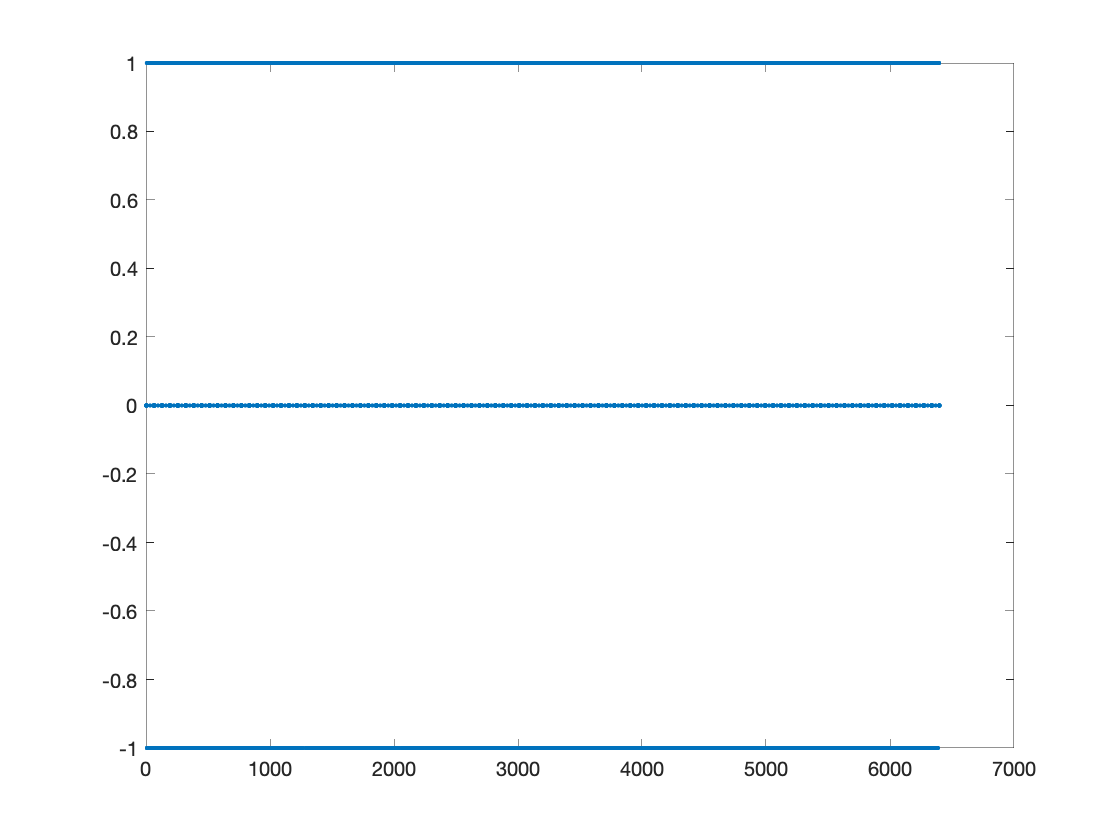

 % Adding pilot tones and guard bands to the data.
%{
    This creates pilot tones and adds guard bands to the data assuming that
    the 0 frequency component is in the middle. This data will be
    fftshifted before it is continued to be processed for sending.
%}
left_guard = zeros(6,1).';
right_guard = zeros(5,1).';
tx_pilot = [];
tx_channel_no_guard = [];
stop_point = (block_num * data_len) - (data_len - 1);
for i = 1 : data_len : stop_point
    curr_block = tx(i:(i+data_len - 1));
    left_block = [curr_block(1:6) 1 curr_block(7:18) 1 curr_block(19:24)];
    right_block = [curr_block(25:30) 1 curr_block(31:42) 1 curr_block(43:48)];
    block_guard = [left_guard left_block 0 right_block right_guard];
    % 13, 26, 40, 53 should be pilot tones
    tx_channel_no_guard = [tx_channel_no_guard left_block right_block];
    tx_pilot = [tx_pilot block_guard];
end
figure
plot(tx_pilot, '.')

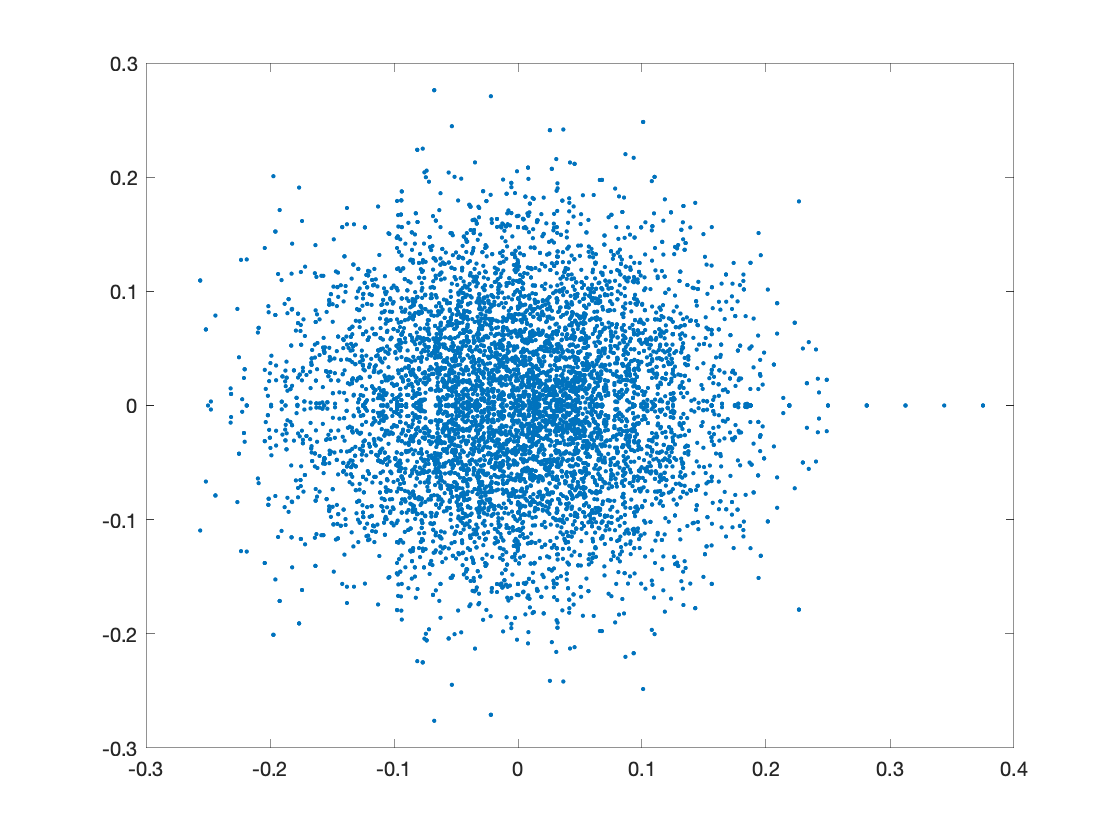

%% Adding the cyclic prefix to the signal and converting to the time domain.
%{
    For each block, the IDFT is taken and then the cyclic prefix is added.
    The cyclic prefix length is 16. So, the final block length will be
    80. Since 100 blocks are being sent, the final length will be 8000.
%}
tx_prefix = prefix_long(tx_pilot, block_len, prefix_len, block_num);
figure
plot(tx_prefix, '.'); % this plot matches the other code correctly

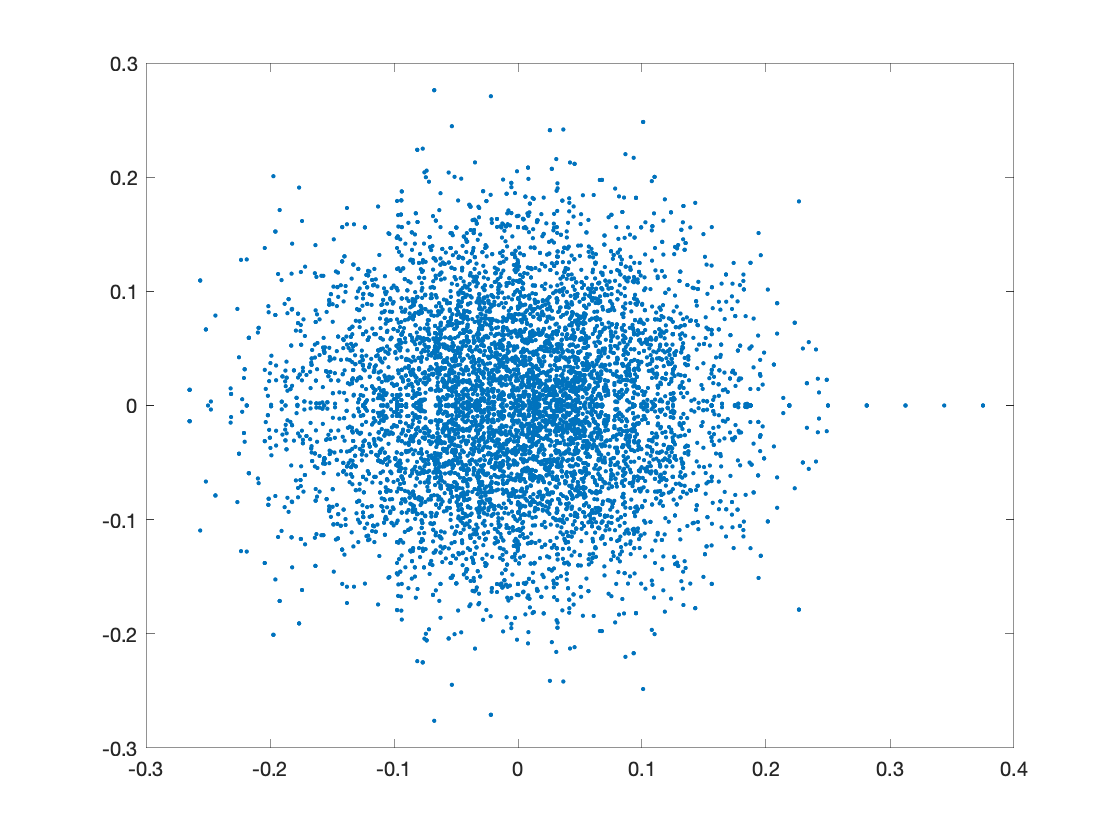

%% Generating the prefix
%{
    This generates the prefix that will be added to the cyclic prefixed
    data. There is also an alternating sequence appended to the beginning 6
    times in order to accurately find the beginning of the data. There were
    issues previously with just using the preamble to find the beginning of
    the data, so this alternating sequence helps this happen.
%}
lts = ifft(fftshift(gen_data(1, block_len))); % 1x64 -> this is the only thing that has changed

% Constructing the preamble by copying the LTS 3 times.
preamble = [lts lts lts];

% Append the preamble.
tx_preamble = [preamble tx_prefix];

figure
plot(tx_preamble, '.');

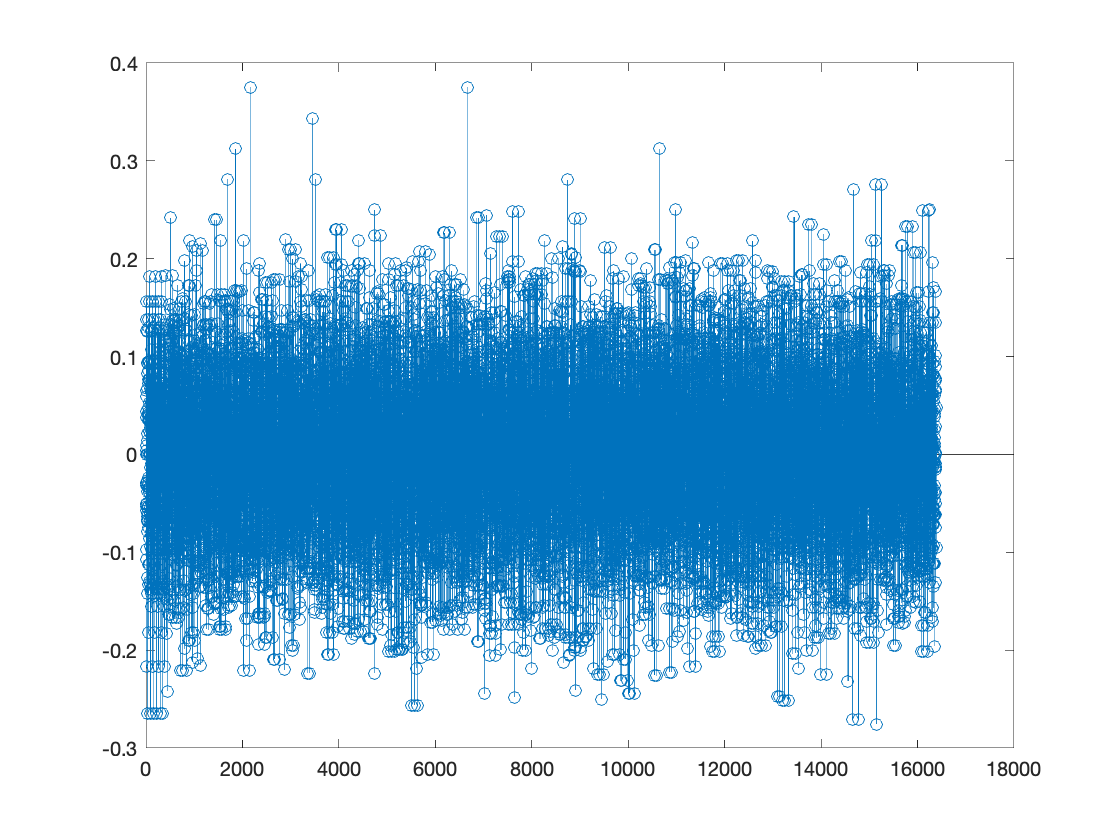

% Save the file to a .dat format for sending over USRP.
tmp = zeros(length(tx_preamble)*2, 1);

tmp(1:2:end) = real(tx_preamble);
tmp(2:2:end) = imag(tx_preamble);

figure
stem(tmp)

f1 = fopen('tx.dat', 'wb');
% write the values as a float32 
fwrite(f1, tmp, 'float32');
% close the file
fclose(f1);

clear ans block curr_block f1 gen_data_len i lts left_guard right_guard stop_point tmp tx_pilot tx_preamble tx_prefix

save("tx_hardware.mat");